clear all
f = @(x1, x2) x1 + 2*x2;
g = @(x1, x2) (1/4)*x1.^2 + x2.^2 - 1

g = function_handle with value:
    @(x1,x2)(1/4)*x1.^2+x2.^2-1


L = @(x1, x2, lam, mu) f(x1, x2) + lam*g(x1, x2) + ...
    (mu/2)*g(x1, x2).^2

L = function_handle with value:
    @(x1,x2,lam,mu)f(x1,x2)+lam*g(x1,x2)+(mu/2)*g(x1,x2).^2



gcb = @(x) sqrt(-(1/4)*x.^2 + 1)

gcb = function_handle with value:
    @(x)sqrt(-(1/4)*x.^2+1)


f1 = @(x) x(1) + 2*x(2);
g1 = @(x) (1/4)*x(1).^2 + x(2).^2 - 1;

clf; clc;
x1 = -3:0.1:3; x2 = -3:0.1:3;
x1s = -2:0.01:2;
[X1, X2] = meshgrid(x1, x2);

stepsize = [0, 3, 4, 10];
k = stepsize(4);
xs_P = zeros(k, 2);

x0 = [1, 1.5];
x01 = x0;
xs_P(1,:) = x0;
lam1 = 0; rho = 1.1; mu1 = 0.5;
xs_P(1,:) = x0;

contour(X1, X2, f(X1, X2), LineStyle='--');

hold on
plot(x1s, gcb(x1s), linewidth=1, color='b')
plot(x1s, -gcb(x1s), linewidth=1, color='b')
levels = -20:1:20;
contour(X1, X2, L(X1, X2, 0, 0.5),levels , color='k', linewidth=1)



for ii = 1:k    
    obj = @(x) f1(x) + lam1*g1(x) + (mu1/2)*g1(x).^2
    options = optimoptions(@fminunc);
    x = fminunc(obj, x0, options);

    xs_P(ii+1,:) = x
   
    lam1 = lam1 + mu1*g1(x)
    mu1 = rho*mu1
    x0 = x
end

obj = function_handle with value:
    @(x)f1(x)+lam1*g1(x)+(mu1/2)*g1(x).^2



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


xs_P =     1.0000    1.5000
   -2.3307   -1.1654
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


lam1 = 0.8581

mu1 = 0.5500

x0 =    -2.3307   -1.1654


obj = function_handle with value:
    @(x)f1(x)+lam1*g1(x)+(mu1/2)*g1(x).^2



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


xs_P =     1.0000    1.5000
   -2.3307   -1.1654
   -1.7454   -0.8727
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


lam1 = 1.1459

mu1 = 0.6050

x0 =    -1.7454   -0.8727


obj = function_handle with value:
    @(x)f1(x)+lam1*g1(x)+(mu1/2)*g1(x).^2



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


xs_P =     1.0000    1.5000
   -2.3307   -1.1654
   -1.7454   -0.8727
   -1.5628   -0.7814
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


lam1 = 1.2797

mu1 = 0.6655

x0 =    -1.5628   -0.7814


obj = function_handle with value:
    @(x)f1(x)+lam1*g1(x)+(mu1/2)*g1(x).^2



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


xs_P =     1.0000    1.5000
   -2.3307   -1.1654
   -1.7454   -0.8727
   -1.5628   -0.7814
   -1.4844   -0.7422
         0         0
         0         0
         0         0
         0         0
         0         0


lam1 = 1.3474

mu1 = 0.7321

x0 =    -1.4844   -0.7422


obj = function_handle with value:
    @(x)f1(x)+lam1*g1(x)+(mu1/2)*g1(x).^2



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


xs_P =     1.0000    1.5000
   -2.3307   -1.1654
   -1.7454   -0.8727
   -1.5628   -0.7814
   -1.4844   -0.7422
   -1.4472   -0.7236
         0         0
         0         0
         0         0
         0         0


lam1 = 1.3820

mu1 = 0.8053

x0 =    -1.4472   -0.7236


obj = function_handle with value:
    @(x)f1(x)+lam1*g1(x)+(mu1/2)*g1(x).^2



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


xs_P =     1.0000    1.5000
   -2.3307   -1.1654
   -1.7454   -0.8727
   -1.5628   -0.7814
   -1.4844   -0.7422
   -1.4472   -0.7236
   -1.4293   -0.7147
         0         0
         0         0
         0         0


lam1 = 1.3993

mu1 = 0.8858

x0 =    -1.4293   -0.7147


obj = function_handle with value:
    @(x)f1(x)+lam1*g1(x)+(mu1/2)*g1(x).^2



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


xs_P =     1.0000    1.5000
   -2.3307   -1.1654
   -1.7454   -0.8727
   -1.5628   -0.7814
   -1.4844   -0.7422
   -1.4472   -0.7236
   -1.4293   -0.7147
   -1.4209   -0.7104
         0         0
         0         0


lam1 = 1.4076

mu1 = 0.9744

x0 =    -1.4209   -0.7104


obj = function_handle with value:
    @(x)f1(x)+lam1*g1(x)+(mu1/2)*g1(x).^2



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


xs_P =     1.0000    1.5000
   -2.3307   -1.1654
   -1.7454   -0.8727
   -1.5628   -0.7814
   -1.4844   -0.7422
   -1.4472   -0.7236
   -1.4293   -0.7147
   -1.4209   -0.7104
   -1.4170   -0.7085
         0         0


lam1 = 1.4114

mu1 = 1.0718

x0 =    -1.4170   -0.7085


obj = function_handle with value:
    @(x)f1(x)+lam1*g1(x)+(mu1/2)*g1(x).^2



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


xs_P =     1.0000    1.5000
   -2.3307   -1.1654
   -1.7454   -0.8727
   -1.5628   -0.7814
   -1.4844   -0.7422
   -1.4472   -0.7236
   -1.4293   -0.7147
   -1.4209   -0.7104
   -1.4170   -0.7085
   -1.4153   -0.7077


lam1 = 1.4131

mu1 = 1.1790

x0 =    -1.4153   -0.7077


obj = function_handle with value:
    @(x)f1(x)+lam1*g1(x)+(mu1/2)*g1(x).^2



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


xs_P =     1.0000    1.5000
   -2.3307   -1.1654
   -1.7454   -0.8727
   -1.5628   -0.7814
   -1.4844   -0.7422
   -1.4472   -0.7236
   -1.4293   -0.7147
   -1.4209   -0.7104
   -1.4170   -0.7085
   -1.4153   -0.7077


lam1 = 1.4138

mu1 = 1.2969

x0 =    -1.4146   -0.7073


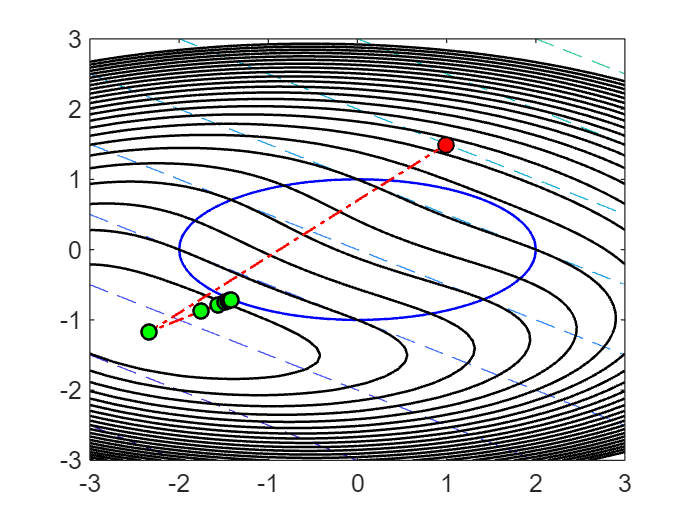


plot(xs_P(1:10,1), xs_P(1:10,2),'ro-.', 'MarkerFaceColor','g', ...
    'linewidth',1, 'MarkerEdgeColor','k')
plot(x01(1,1), x01(1,2),'ro','MarkerFaceColor','r','MarkerEdgeColor','k' )

hold off